# Kubische Splineinterpolation

Wir betrachten die kubische Spline-Interpolationsaufgabe auf dem Intervall $[0,1]$, mit  äquidistanten Stützstellen $x_j=j*h$, $j=0,\ldots,n$, $nh=1$:

                  $\text{Finde}~~S \in \mathbb{P}_{4,\tau}=\{\, g \in C^2([0,1])~|~g_{|[x_i,x_{i+1}]} \in \Pi_3,~i=0,\ldots, n-1\,\}$  so dass $S(x_j)=f(x_j),~~j=0,\ldots,n.$

Die Daten $f(x_j)$ sind die Werte einer stückweise glatten Funktion

    
$$f(x)=\begin{cases} 
  \sin(10x) +1.2 & \text{f\"ur } x\in[0,a_1),\\
  \frac12 & \text{f\"ur } x\in [a_1,a_2), \\
  e^x & \text{f\"ur } x\in [a_2,1],
\end{cases}$$
 

mit Parameterwerten $0<a_1<a_2<1$.

Der $n$-Wert und die Parameterwerte $0< a_1   <  a_2 <1$ werden gesetzt und die Datenpunkte werden geplottet:

n=20;
a=[0.4, 0.75];
Knoten=linspace(0,1,n+1)';
Daten=zeros(n+1,1);
for i=1:n+1
    Daten(i)=F(Knoten(i),a);
end
plot(Knoten,Daten,'*');
hold on

Die Funktion $f$ und die Spline-Interpolation werden auf einem äquidistanten Gitter mit Schrittweite $10^{-2}$ ausgewertet und geplottet.

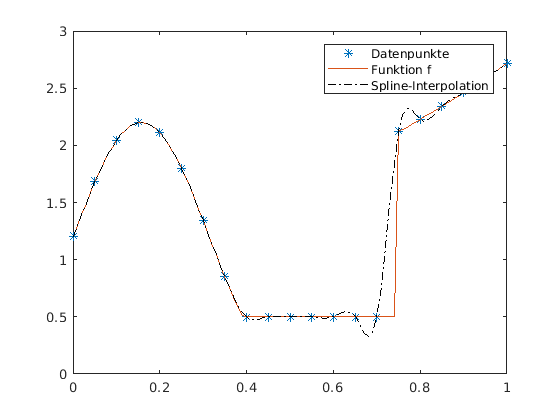

mplot=101;
x=linspace(0,1,mplot);
Spline=zeros(mplot,1);
f=zeros(mplot,1);
for i=1:mplot
    f(i)=F(x(i),a);
    Spline(i)=spline(x(i),Daten);
end
plot(x,f,'-', x,Spline,'k-.');
legend('Datenpunkte','Funktion f','Spline-Interpolation');
hold off;

# Aktivität:

 Variieren Sie den $n$-Wert und die Parameterwerte $a_i$ und beobachten Sie die Effekte.

function y=F(x,a)
% wertet die parameterabhaengige Funktion f an der Stelle x aus.
    if (x<a(1)) 
        y=sin(10*x) + 1.2;
    elseif (x>=a(2))
        y=exp(x);
    else 
        y=0.5;
    end
 end


function y=spline(x,f)
% Diese Funktion wertet die kubische Splineinterpolation mit äquidistanten Stützstellen und Daten f an der Stelle x aus.
    n=length(f)-1; h=1/n;
    Knoten=(0:h:1)';
    A=full(gallery('tridiag',n-1,1,4,1));
    b=zeros(n-1,1);
    for i=1:n-1
        b(i)=f(i) - 2*f(i+1) + f(i+2);   
    end
    mt=A\(6/(h^2)*b);
    m=zeros(n+1,1); m(2:n)=mt;
    for j=1:n
        xleft=Knoten(j); xright=Knoten(j+1);
        if ((xleft<=x) && (x <=xright)) % x liegt im Teilintervall
            y= ((xright-x)^3*m(j) + (x-xleft)^3*m(j+1))/(6*h) ...
             + ((xright-x)*f(j) + (x-xleft)*f(j+1))/h - h*((xright-x)*m(j) + (x-xleft)*m(j+1))/6;
            return
        end
    end 
end